This is an algorithm used to simulate evolutionary algorithms

In this algorithm, a set of bit strings is generated randomly, with a population of n.

During the each interation, one string will be selected according to algorithm rules, then each bit will be flipped at the possibility of 1/n.

After this step, the mutated bit string is added to the population, and the one with least fitness will be eliminated, keeping the population unchanced.

The function to be optimized is called twomax. twomax = max(num of 1s, num of 0s).

Through numerical experiments, inverse elitist method and inverse tournament method are found to be able to preserve population diversity.

More on [On Steady-State Evolutionary Algorithms and Selective Pressure: Why Inverse Rank-Based Allocation of Reproductive Trials Is Best | ACM Transactions on Evolutionary Learning and Optimization](https://dl.acm.org/doi/10.1145/3427474)

clear
global n;
global miu;
n = 30;%length of each sequence
miu = 50;%group size
k = 2;%inverse tournament size
T = 1e4;
f = @(x)twomax(x);
Species = generator(n,miu);
%%
SpeciesU = Species;% generate
SpeciesK = Species;
SpeciesE = Species;
s = linspace(0,1,miu);
DiversityU = zeros(T,1);
DiversityK = DiversityU;
DiversityE = DiversityU;
HistorygramE = zeros(n,T);
HistorygramK = HistorygramE;
f = @(x)twomax(x);
clf

execute simulation

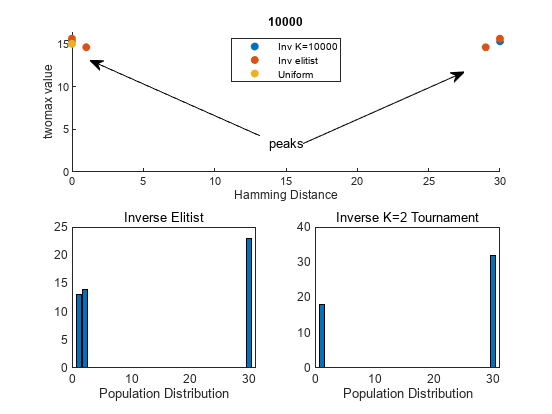

for t = 1:T
    SpeciesK = inverseK_EA(SpeciesK,f,k);
    DiversityK(t) = sum(var(SpeciesK))*miu;
    HistorygramK(:,t) = histcounts(hammingDist(0,SpeciesK),0:n);

    SpeciesE = InverseElitistEA(SpeciesE,f);
    DiversityE(t) = sum(var(SpeciesE))*miu;
    HistorygramE(:,t) = histcounts(hammingDist(0,SpeciesE),0:n);

    SpeciesU = standardEA(SpeciesU,f);
    DiversityU(t) = sum(var(SpeciesU))*miu;

    if mod(t,5e2)==0
        grid on
        subplot(2,2,3)
        bar(HistorygramE(:,t))
        subtitle('Inverse Elitist')
        xlabel('Population Distribution')
        subplot(2,2,4)
        bar(HistorygramK(:,t))
        subtitle(sprintf('Inverse K=%d Tournament',k))
        xlabel('Population Distribution')
        subplot(2,2,1:2)
        hold off
        scatter(hammingDist(zeros(1,n),SpeciesK),f(SpeciesK)+0.3,'filled')
        hold on
        scatter(hammingDist(zeros(1,n),SpeciesE),f(SpeciesE)+0.6,'filled')  
        scatter(hammingDist(zeros(1,n),SpeciesU),f(SpeciesU),'filled')
        xlim([0,n])
        ylim([0,n*0.55])
        title(t)
        legend(sprintf('Inv K=%d',t),'Inv elitist','Uniform',Location='north')
        xlabel('Hamming Distance')
        ylabel('twomax value')
        annotation("arrow", [0.4696 0.1625], [0.6728 0.8548])
        annotation("textarrow", [0.55 0.8411], [0.6538 0.8262], "String", "peaks")
        drawnow
    end
end

you can see how the pupulation diversity changes over generation in each algorithm

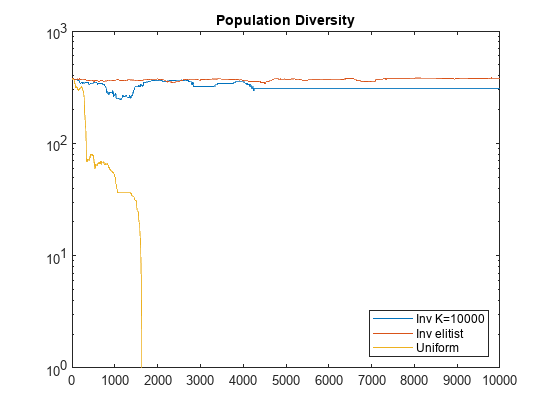

clf
semilogy(DiversityK)
hold on
semilogy(DiversityE)
semilogy(DiversityU)
title('Population Diversity')
legend(sprintf('Inv K=%d',k),'Inv elitist','Uniform',Location='southeast')

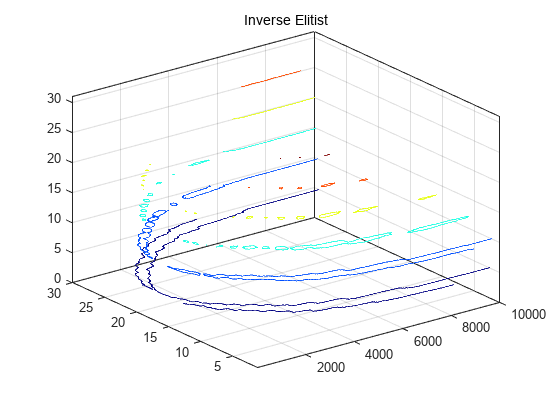

clf
[X,Y] = meshgrid(1:t,1:n);
colormap jet
contour3(HistorygramE)
subtitle('Inverse Elitist')

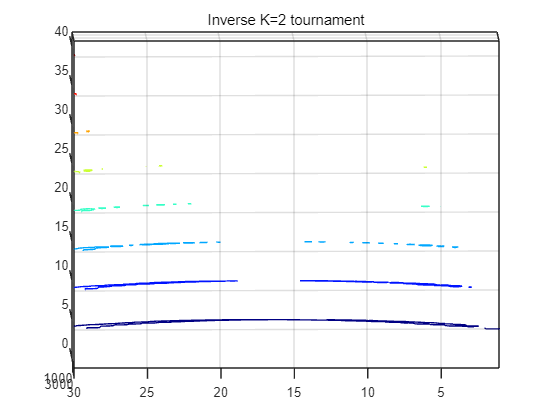

figure(2)
contour3(HistorygramK(:,1:3000))
%surf(X,Y,HistorygramK,EdgeColor="none")
view([-44.7 57.6])
subtitle(sprintf('Inverse K=%d tournament',k))

Problem2

clear
clf
T = 0:0.1:30;
X = T.*sin(T);
Y = T.*cos(T);


method 1

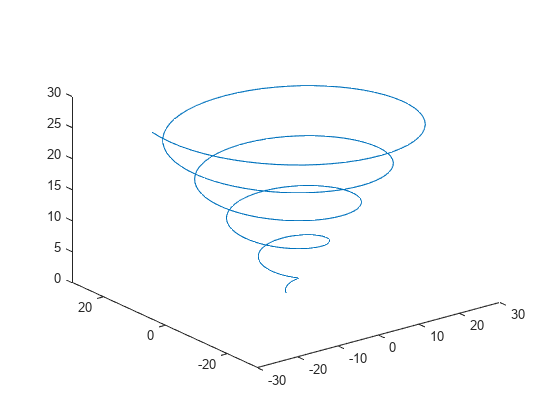

for t = 1:length(T)
    plot3(X(1:t),Y(1:t),T(1:t));
    xlim([-30,30])
    ylim([-30,30])
    zlim([0,30])
    drawnow
end

method 2

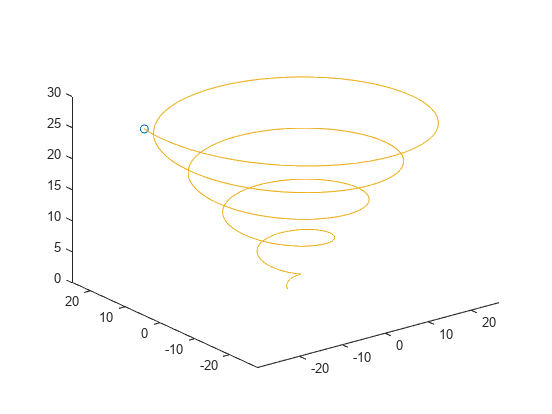

comet3(X,Y,T,0.05)

method 3

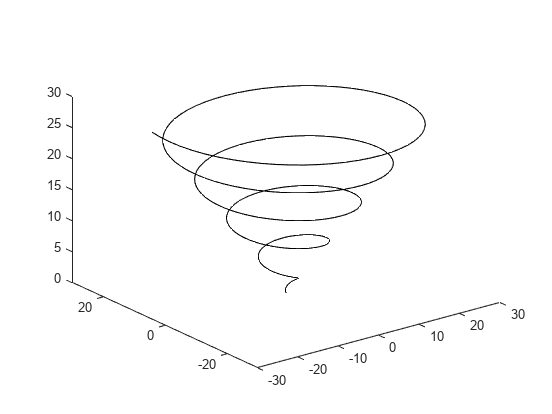

clf
ln = animatedline('MaximumNumPoints', 301);
view(3);
xlim([-30,30])
ylim([-30,30])
zlim([0,30])
for t = 1:length(T)
    addpoints(ln,X(t),Y(t),T(t));
    exportgraphics(gcf,'hw2problem2.gif','Append',true);
    drawnow
end

problem 3

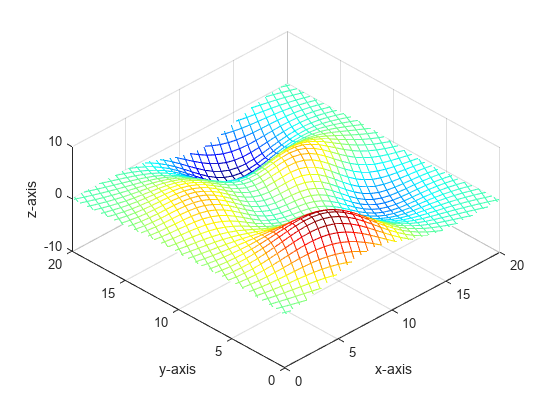

x=linspace(10-10*sqrt(2),10+10*sqrt(2),50);
[X,Y] = meshgrid(x,x);
s = mesh(X,Y,peaks(50));

direction = [0 0 1];
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
xlim([0,20])
ylim([0,20])
zlim([-10,10])
view([-44.7 57.6])
for t = 1:0.1:5*pi
    rotate(s,direction,t,[10,10,0])
    pause(0.1)
    exportgraphics(gcf,'hw2problem3.gif','Append',true);
    drawnow
end

problem 4

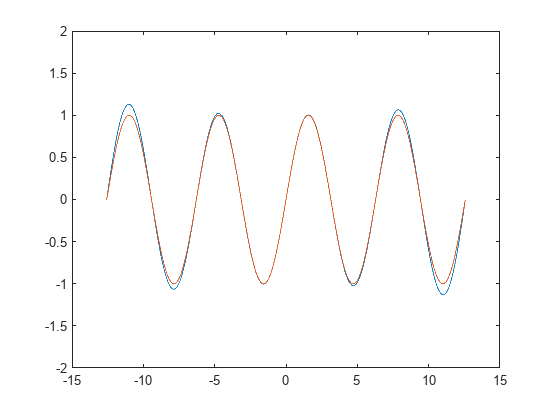


X = linspace(-4*pi,4*pi,1e4);
for n = [5,8,10,50,100]
    clf
    Expression = zeros(n,length(X));
    for k = 1:n
        Expression(k,:) = (1 - X.^2/(pi^2*k^2));
    end
    fx = prod(Expression,1).*X;
    plot(X,fx)
    hold on
    plot(X,sin(X))
    ylim([-2,2])
    pause(1)
end

function newP = standardEA(P,f)
global miu;
x = P(randi([1,miu]),:);% Choose x ∈ Pt uniformly at random
y = arrayfun(@(bit)bitFlipping(bit),x);% Create y by flipping each bit in x independently with probability 1/n.
P = [P;y];
[~,score] = sort(f(P),"descend");
newP = P(score(1:miu),:);
end

function newP = inverseK_EA(P,f,k)
global miu;
X = P(randperm(miu,k),:);% Choose Xs ∈ P_t uniformly at random
Score = f(X);
minimum = min(Score);%perform inverse tournament
Location = find(Score==minimum);
Candidate = X(Location,:);
x = Candidate(randperm(length(Location),1),:);%pick one of the worst
y = arrayfun(@(bit)bitFlipping(bit),x);% Create y by flipping each bit in x independently with probability 1/n.
P = [P;y];
[~,Rank] = sort(f(P),"descend");%pop out the worst
newP = P(Rank(1:miu),:);
end


function newP = InverseElitistEA(P,f)
global miu;
Value = f(P);%Compute all value
[~,score] = sort(f(P),"descend");
P = P(score,:);
Value = Value(score,:);%Rearrange the value as well
min_x_num = sum(Value==Value(miu));%Get the list of the inverse elitist
x = P(miu-randi([0,min_x_num-1]),:);% Choose one of the inverse elitist, which is from miu-min_x_num+1:miu
y = arrayfun(@(bit)bitFlipping(bit),x);% Create y by flipping each bit in x independently with probability 1/n.
if f(y)>f(x)
    P(miu,:) = y;
end
newP = P;
end

function Y = generator(n,miu)
% This function is used to generate miu binary sequences whose length is n.
Y = logical(randi([0,1],miu,n));
end

function Y = twomax(X)
% This function is used as test function.
global n;
O = false(1,n);
Y = abs(hammingDist(O,X)-n/2);
end

function Y = truncatedTwomax(X,k)
% This function is used as test function.
global n;
Dist = hammingDist(false(1,n),X);
Y = abs(Dist-n/2).*(Dist>n/2-k);
end

function H = hammingDist(x,Y)
% This function is used to calculate the hamming distances between x and Ys, where Y could be multiple points.
X = repmat(x,height(Y),1);
H = sum(bitxor(X,Y),2);
end

function newbit = bitFlipping(bit)
global n;
probability = rand*n<1;
if probability
    newbit = ~bit;
else
    newbit = bit;
end
end